# **Long-term time-series forecasting**

`Authors:`

- `Francesco Amato`

- `Francesco Minaglia`

- `Filippo Maria Rognoni`

## *0. Preliminary actions*

Before starting could be useful to "clean" matlab workspace, in order to see only results that concerns our project

clc; %Clear command window content
clear; % Remove variables saved in workspace
close all; % Close all the window/figures opened before

## *1. Introduction*

The aim of this project is to identify an annual profile model for the long-term forecast of the time-series. 

The process is refered to gas consumption in Italy, in two different year, in function of a day of the week and a day of an year.

Finally, once identified the best model we create a function that predict the gas consumption in function of two parameters (day of the week, day of the year).

## ***2. Process visualization***

Before starting identifying the best model, it is useful to have some ideas on the process function characteristics plotting it in three different ways:  

- 2D:  gas consumption in function of the day of the year;

- Spectral analysis: to see what are the repetition that characterize our signal; 

- 3D: gas consumption in function of the day of the year, and the day of the week.

### 2.1 Plotting 2D

Before plotting it is useful to save both years information in two different variables.

% Save the table information in two dataset, each for a year
% selecting only the data I’m interested viewing
dsYear1=readtable('../Dataset/gasITAday.xlsx', 'Range', 'A3:C367');

dsYear2=readtable('../Dataset/gasITAday.xlsx', 'Range', 'A368:C732');


% Change the coloumn's name in the different datasets
dsYear1.Properties.VariableNames{1}='DayOfTheYear';
dsYear1.Properties.VariableNames{2}='DayOfTheWeek';
dsYear1.Properties.VariableNames{3}='GasConsumption';

dsYear2.Properties.VariableNames{1}='DayOfTheYear';
dsYear2.Properties.VariableNames{2}='DayOfTheWeek';
dsYear2.Properties.VariableNames{3}='GasConsumption';

Now we are able to visualize both years data in different plots.

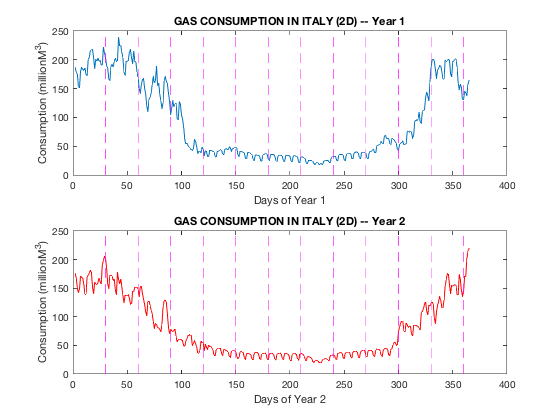

figure()
%Year 1
subplot(2,1,1)
plot(dsYear1.DayOfTheYear,dsYear1.GasConsumption);
title('GAS CONSUMPTION IN ITALY (2D) -- Year 1');
xlabel('Days of Year 1');
ylabel('Consumption (millionM^3)');
% Added vertical lines to see better the different months gas consumption
for i = 1:12
       xline(i*30, 'm--');
end
%Year 2
subplot(2,1,2)
plot(dsYear2.DayOfTheYear,dsYear2.GasConsumption,'r');
title('GAS CONSUMPTION IN ITALY (2D) -- Year 2');
xlabel('Days of Year 2');
ylabel('Consumption (millionM^3)');
% Added vertical lines to see better the different months gas consumption
for i = 1:12
       xline(i*30, 'm--');
end

*FIRST OBSERVATION:*

From the diagrams we can notice that the gas consumption decreases in the hottest months of the year, more specifically starting from the 120th (April) to the 290th (September). So we can say that this trend is seasonal, with a periodicity of about 6 months.

*WHY IT HAPPENS? *

Natural gas consumption has two seasonal peaks, largely reflecting weather-related fluctuations in energy demand. In the winter months, cold weather leads to an increase of the demand of gas due to residential heating and commercial use. Meanwhile in the summer months, warmer weather leads to an increase of the air conditioning demand and, consequently, a major demand for electricity.

*ANOTHER OBSERVATION:*

Considering a specific weekly window (7 days), we notice that during the weekend the gas consumption is lower than on the other five days of the same week. This phenomenon is probably caused by the factory closure.

The previous comment could be seen taking a week randomly:

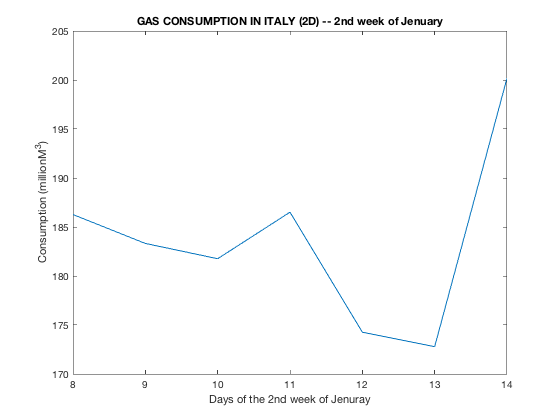

figure()
% Notice that 7 is monday, 13 is Sunday
plot(dsYear1.DayOfTheYear(7:13),dsYear1.GasConsumption(7:13));
title('GAS CONSUMPTION IN ITALY (2D) -- 2nd week of Jenuary');
xlabel('Days of the 2nd week of Jenuray');
ylabel('Consumption (millionM^3)');

*SOME MATHEMATICAL OBSERVATIONS: *

We notice that it is a [discrete time](https://en.wikipedia.org/wiki/Discrete_time_and_continuous_time) [stationary](https://en.wikipedia.org/wiki/Stationary_process) process.

**Stationary** because if we took two sufficiently distant windows we would see a trend similar to the previous one (except for small oscillations caused by noise). Specifically talking about our dataset we see this phenomenon considering six months windows.

**Discrete time** because the realizations were taken only once per day during the year and not for every moment of time.

Another remarkable characteristic is that the process is [**ergodic**](https://en.wikipedia.org/wiki/Ergodic_process)**: ***"its statistical properties can be deduced from a single, sufficiently long, random sample of the process. The reasoning is that any collection of random samples from a process must represent the average statistical properties of the entire process. In other words, regardless of what the individual samples are, a birds-eye view of the collection of samples must represent the whole process. Conversely, a process that is not ergodic is a process that changes erratically at an inconsistent rate".*

Finally we can say that its [**autocovariance function**](https://en.wikipedia.org/wiki/Autocovariance) will be higher at 0, and after six months we find about the some relationship (after six months there's an increasing in gas consumption cause by the decrease of temperature).

Here is the code that shows the characteristics above. It's easy to see (just changing dsYear1, to dsYear2) that the first process autocovariance (gas consumption during the first year) is similar to the autocovariance of the second one (gas consumption during the second year).

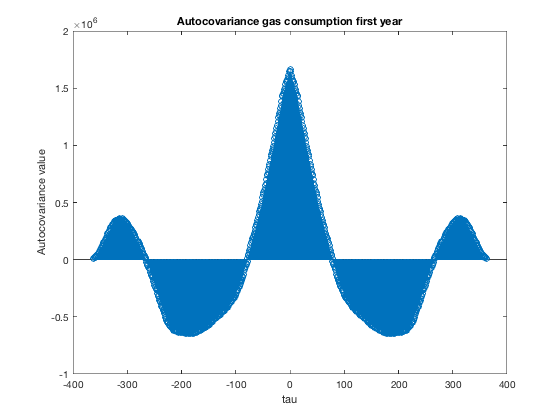

[c,lags] = xcov(dsYear1.GasConsumption);
stem(lags,c)
title('Autocovariance gas consumption first year');
xlabel('tau');
ylabel('Autocovariance value'); 

### 2.2 Spectral analysis

Another process visualization that allows to notice different signal characteristics is bound to the frequency domain. This domain can be very useful to understand and **highlight** **signal's repetitions**. 

In order to change time domain, we use the Fourier transform of our signal. 

We expect frequencies that reflect some repetitions, and these will be: 

- the *constant trend*, during an entire year of gas consumption; 

- the *annual repetition*; 

- the *semestral repetition*;

- the *weekly repetition*.

To represent what was said previously, we should connect the gas consumption of the two years.

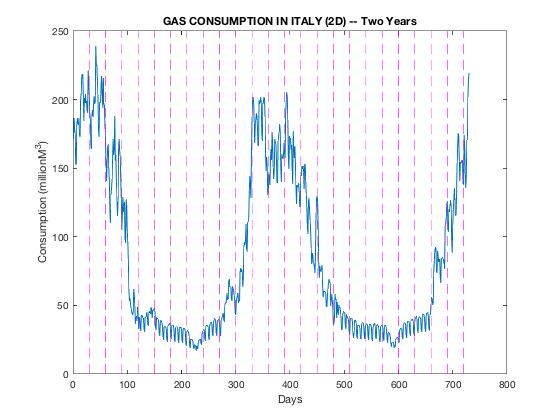

% days of both years
days = linspace(1,730,730)';
%week days of both years
daysWeek = table2array(readtable('../Dataset/gasITAday.xlsx', 'Range', 'B2:B732'));
% gas consumption during both years
gas_consumption = table2array(readtable('../Dataset/gasITAday.xlsx', 'Range', 'C2:C732'));

% Plotting two years gas consumption trend
figure()
plot(days,gas_consumption);
title('GAS CONSUMPTION IN ITALY (2D) -- Two Years');
xlabel('Days');
ylabel('Consumption (millionM^3)');
% Added vertical lines to see better the different months gas consumption
for i = 1:24
       xline(i*30, 'm--');
end

Once we've represented our two years gas consumption trend, lets perform the [**fast fourier transform**](https://en.wikipedia.org/wiki/Fast_Fourier_transform), in order to obtain the spectrum of our signal.

The aim of the next script is to use Fourier transforms, to find the frequency components of a signal covered by noise.

Before performing FFT ( *Fast Fourier Transform *), having some variables could be useful:

% Specify the parameters of a signal with a sampling frequency of 1 kHz 
% and a signal duration of 0.730 seconds.
Fs = 1000;                    % Sampling frequency                    
T = 1/Fs;                     % Sampling period       
L = length(days);             % Length of signal (number of days)
t = (0:L-1)*T;                % Time vector

Now we're ready to see the signal's spectrum (violet).

%Plotting the signal's spectrum
figure(2)
% Compute the Fourier transform of the signal
signalSpectrum=fft(gas_consumption);
% Compute the two-sided spectrum P2. Then compute the single-sided spectrum 
% P1 based on P2 and the even-valued signal length L.
P2 = abs(signalSpectrum/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
% Define the frequency domain f and plot the single-sided amplitude spectrum P1.
% The amplitudes are not exactly at 0.7 and 1, as expected, because of the added 
% noise. On average, longer signals produce better frequency approximations.
f = linspace(1,366,366);
plot(f,P1,'m'); 
grid on
title('SPECTRUM OF THE GAS CONSUMPTION FUNCTION, 2 years');
xlabel('frequency')
ylabel('FFT Gas Consumption')

Now we want display the position of the most **important peaks** (blue) of the spectrum.

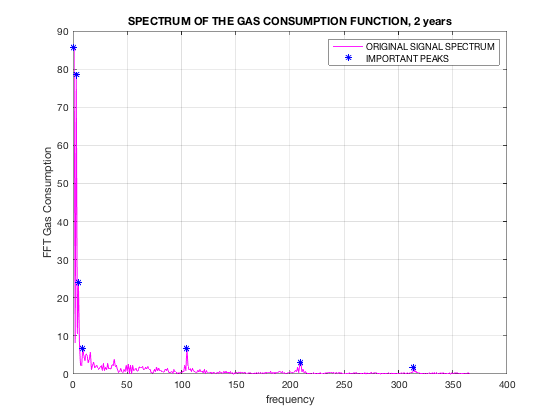

hold on
%Find important peaks of the signal spectrum
[amp,locs] = findpeaks(P1);
% Because findpeaks function does not find the peak in 0, we insert it
% manually
ampPeakIn0= 85.61;
%Show only important peaks on plot shown before
locsImpPeaks= [locs(1:3);locs(41);210;314];
ampImpPeaks= [amp(1:3);amp(41);2.921;1.696];
plot([0;locsImpPeaks],[ampPeakIn0;ampImpPeaks],'b*');
legend('ORIGINAL SIGNAL SPECTRUM','IMPORTANT PEAKS')

Note that these frequencies are the same that we identified in the initial part of this section: 

- *Frequency in 0*: costant trend that represent the mean gas consumption in both years;

- *Frequency in 2*: yearly seasonality, taken the annual trend it repeats twice (considered two years); 

- *Frequency in 4:* semestral seasonality, taken the semestral trend it repeats twice in an year (four times in two years); 

- *Frequency in 104*: weekly seasonality, since an year has 52 weeks (considered two years there are 104 weeks).

Spectral analysis shows also other repetitions that we had not previously observed. These frequencies are highlighted in the graph on the right:

- *Frequency in 8:*  three-months seasonality;

- *Frequency in 209*: four days periodicity;

- *Frequency in 313*: two days periodicity.

### 2.3 Plotting 3D

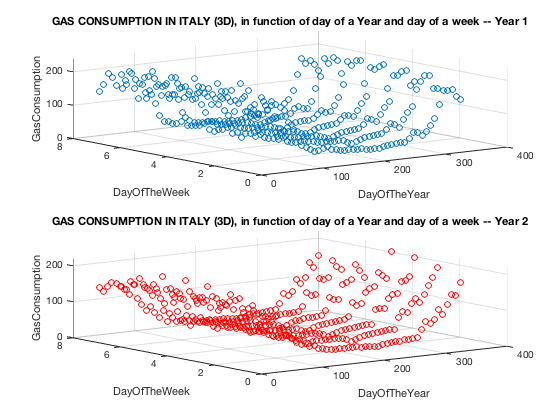

figure()
%Year 1
subplot(2,1,1)
plot3(dsYear1.DayOfTheYear,dsYear1.DayOfTheWeek,dsYear1.GasConsumption,'o');
grid on
title ('GAS CONSUMPTION IN ITALY (3D), in function of day of a Year and day of a week -- Year 1');
xlabel('DayOfTheYear');
ylabel('DayOfTheWeek');
zlabel('GasConsumption');
%Year 2
subplot(2,1,2)
plot3(dsYear2.DayOfTheYear,dsYear2.DayOfTheWeek,dsYear2.GasConsumption,'ro');
grid on
title ('GAS CONSUMPTION IN ITALY (3D), in function of day of a Year and day of a week -- Year 2');
xlabel('DayOfTheYear');
ylabel('DayOfTheWeek');
zlabel('GasConsumption');

## ***3. Model identification***

Since we can identify the model through different methodologies, we have choosen some techniques to do this:

- Polynomial regression

- Neural networks - Mlp

- Harmonic regression

As a criterion for the selection of the method that produces the final model, we choose the one that provides better results than the others.

### 3.1 Polynomial regression

[Polynomial regression method theory. ](https://en.wikipedia.org/wiki/Polynomial_regression)

We are going to use the first year to identify the model/s which is/are better representing our data, to predict also "future"/other data. The second year, instead, will be used to verify if the identification model finded (with the first year) could be precise, or not, according to cross-validation theory. 

Before showing all polynomial models here there are some useful variables:

% USEFUL VARIABLES
n=length(dsYear1.GasConsumption); %Number of observations
nVal=length(dsYear2.GasConsumption); % Number of observation (for validation)
% Array containing all values of the days in a week, that we will consider
daysOfTheWeek_grid=linspace(0,7,100); 
% Array containing all values of the days in a year, that we will consider
daysOfTheYear_grid=linspace(0,365,100); 
% We get the matrices with the two coordinates
[Dy, Dw]=meshgrid(daysOfTheYear_grid, daysOfTheWeek_grid);
Dw_vec=Dw(:);
Dy_vec=Dy(:);
alpha=0.05; %fixed the level of significance

Only seeing the graph (plotting 3D section) showing the identification data we can see that the constant model would be too inaccurate, since the data are aligned along a plane that cuts the z-axis perpendicularly. 

We could also say that the first degree model should not be considered, because the data of gas consumption have a periodic trend and therefore the plan should have deflected at least...so it can not be a plan with a constant slope.

In conclusion it is better to start from a second degree model (parable), and then gradually move to more complex models (in order to evaluate the figures of merit through different criteria and establish the best model).

Before seeing the code here there are some ***theoretical reference: ***

`Remember that: `$Y=\phi \theta +V$`, assuming that `$E\left\lbrack V\right\rbrack =0$` and `

$\textrm{Var}\left\lbrack V\right\rbrack =\sigma^2$` .`

`Moreover: `$\theta^{\textrm{LS}} ={\left(\phi^T \phi \right)}^{-1} \left(\phi^T Y\right)$`, where ^t stands for transposition`

`and `$\textrm{Var}\left\lbrack \theta^{\textrm{LS}} \right\rbrack =\sigma^2 {\left(\phi^T \phi \right)}^{-1}$`, assuming that `$\;\psi =I_n$

$\theta$` is the real parameter, `$\theta^{\textrm{LS}}$` instead is the extimated parameter.`

`Whenever `$\sigma^2$` is not known, how shall we calculate the standard deviation?`

$\sigma^2$` not known => `$\overset{\wedge }{\sigma^2 } =\frac{\textrm{SSR}}{n-q}$

`Where `$\textrm{SSR}=\epsilon^T \epsilon$`,     `$\epsilon =Y-\overset{\wedge }{Y^{\textrm{LS}} }$`,       where `$\overset{\wedge }{Y^{\textrm{LS}} } =\phi \theta^{\textrm{LS}}$

#### 3.1.1 Identification

*a. FIRST DEGREE POLYNOMIAL MODEL*

We consider this model since we may find its merit figures useful, when we will have to compare it to the other more complex models.

Phi1= [ones(n,1), dsYear1.DayOfTheYear, dsYear1.DayOfTheWeek ]; 
[ThetaLS1, std_thetaLS1] = lscov(Phi1, dsYear1.GasConsumption);

% Variables that will be useful to us regarding the choice of
% best model
q1=length(ThetaLS1); %Number of parameters considered by the model in question
%Estimated yield given our model
y_hat1=Phi1*ThetaLS1;
%Residual calculation
epsilon1=dsYear1.GasConsumption-y_hat1;
%SSR calculation
SSR1=epsilon1'*epsilon1;

*b. SECOND DEGREE POLYNOMIAL MODEL*

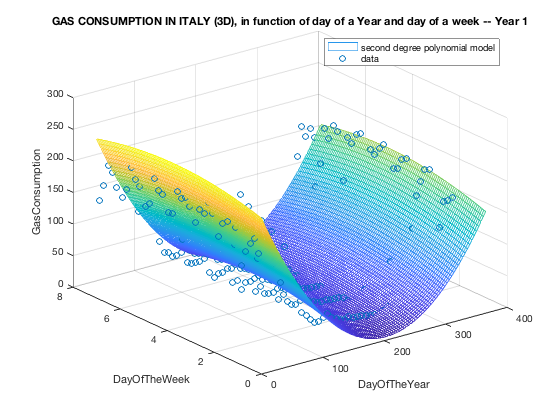

Phi2= [ones(n,1), dsYear1.DayOfTheYear, dsYear1.DayOfTheWeek, (dsYear1.DayOfTheYear).^2 ...
      , (dsYear1.DayOfTheWeek).^2, (dsYear1.DayOfTheYear).*(dsYear1.DayOfTheWeek) ]; 
[ThetaLS2, std_thetaLS2] = lscov(Phi2, dsYear1.GasConsumption);

% Variables that will be useful to us regarding the choice of
% best model
q2=length(ThetaLS2); %Number of parameters considered by the model in question
%Estimated yield given our model
y_hat2=Phi2*ThetaLS2;
%Residual calculation
epsilon2=dsYear1.GasConsumption-y_hat2;
%SSR calculation
SSR2=epsilon2'*epsilon2;

%Showing this model
% We create an ad hoc Phi by inserting as values not the vectors of
% observations, but vectors containing grid values
Phi2_grid=[ones(length(Dy_vec),1), Dy_vec, Dw_vec, Dy_vec.^2, Dw_vec.^2, Dy_vec.*Dw_vec ]; 
shape2=Phi2_grid*ThetaLS2; %shape creation
shape2_matrix=reshape(shape2, size(Dy)); %Transform the shape in a matrix

figure
mesh(Dy,Dw,shape2_matrix);
hold on
%Overlay of observations to our model
plot3(dsYear1.DayOfTheYear, dsYear1.DayOfTheWeek , dsYear1.GasConsumption,'o');
grid on
title ('GAS CONSUMPTION IN ITALY (3D), in function of day of a Year and day of a week -- Year 1');
xlabel('DayOfTheYear');
ylabel('DayOfTheWeek');
zlabel('GasConsumption');
legend('second degree polynomial model' , 'data', 'Location', 'Northeast');

*c. THIRD DEGREE POLYNOMIAL MODEL*

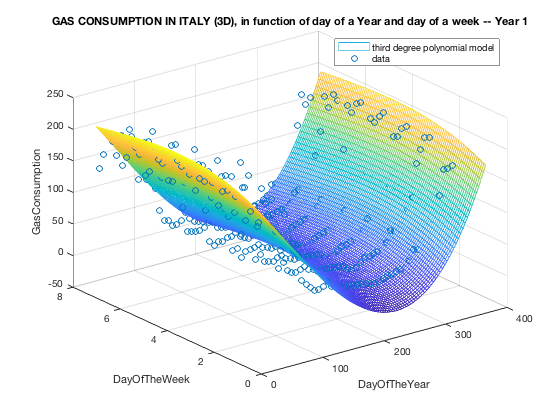

Phi3= [ones(n,1), dsYear1.DayOfTheYear, dsYear1.DayOfTheWeek, (dsYear1.DayOfTheYear).^2 ...
      , (dsYear1.DayOfTheWeek).^2, (dsYear1.DayOfTheYear).*(dsYear1.DayOfTheWeek) ...
      , dsYear1.DayOfTheYear.^3, dsYear1.DayOfTheWeek.^3, (dsYear1.DayOfTheYear.^2).*dsYear1.DayOfTheWeek ...
      , dsYear1.DayOfTheYear.*(dsYear1.DayOfTheWeek.^2)]; 
[ThetaLS3, std_thetaLS3] = lscov(Phi3, dsYear1.GasConsumption);

% Variables that will be useful to us regarding the choice of
% best model
q3=length(ThetaLS3); %Number of parameters considered by the model in question
%Estimated yield given our model
y_hat3=Phi3*ThetaLS3;
%Residual calculation
epsilon3=dsYear1.GasConsumption-y_hat3;
%SSR calculation
SSR3=epsilon3'*epsilon3;

%Showing this model
% We create an ad hoc Phi by inserting as values not the vectors of
% observations, but vectors containing grid values
Phi3_grid=[ones(length(Dy_vec),1), Dy_vec, Dw_vec, Dy_vec.^2, Dw_vec.^2, Dy_vec.*Dw_vec ...
    , Dy_vec.^3, Dw_vec.^3, (Dy_vec.^2).*Dw_vec, Dy_vec.*(Dw_vec.^2) ]; 
shape3=Phi3_grid*ThetaLS3; %shape creation
shape3_matrix=reshape(shape3, size(Dy)); %Transform the shape in a matrix

figure
mesh(Dy,Dw,shape3_matrix);
hold on
%Overlay of observations to our model
plot3(dsYear1.DayOfTheYear, dsYear1.DayOfTheWeek , dsYear1.GasConsumption,'o');
grid on
title ('GAS CONSUMPTION IN ITALY (3D), in function of day of a Year and day of a week -- Year 1');
xlabel('DayOfTheYear');
ylabel('DayOfTheWeek');
zlabel('GasConsumption');
legend('third degree polynomial model' , 'data', 'Location', 'Northeast');

d. *FOURTH DEGREE POLYNOMIAL MODEL*

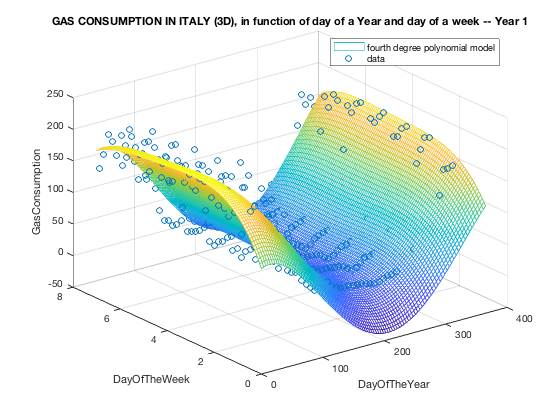

Phi4= [ones(n,1), dsYear1.DayOfTheYear, dsYear1.DayOfTheWeek, (dsYear1.DayOfTheYear).^2 ...
      , (dsYear1.DayOfTheWeek).^2, (dsYear1.DayOfTheYear).*(dsYear1.DayOfTheWeek) ...
      , dsYear1.DayOfTheYear.^3, dsYear1.DayOfTheWeek.^3, (dsYear1.DayOfTheYear.^2).*dsYear1.DayOfTheWeek ...
      , dsYear1.DayOfTheYear.*(dsYear1.DayOfTheWeek.^2) ... 
      , dsYear1.DayOfTheYear.^4, dsYear1.DayOfTheWeek.^4, (dsYear1.DayOfTheYear.^3).*dsYear1.DayOfTheWeek...
      , (dsYear1.DayOfTheYear.^2).*(dsYear1.DayOfTheWeek.^2) ...
      , dsYear1.DayOfTheYear.*(dsYear1.DayOfTheWeek.^3)]; 
[ThetaLS4, std_thetaLS4] = lscov(Phi4, dsYear1.GasConsumption);

% Variables that will be useful to us regarding the choice of
% best model
q4=length(ThetaLS4); %Number of parameters considered by the model in question
%Estimated yield given our model
y_hat4=Phi4*ThetaLS4;
%Residual calculation
epsilon4=dsYear1.GasConsumption-y_hat4;
%SSR calculation
SSR4=epsilon4'*epsilon4;

%Showing this model
% We create an ad hoc Phi by inserting as values not the vectors of
% observations, but vectors containing grid values
Phi4_grid=[ones(length(Dy_vec),1), Dy_vec, Dw_vec, Dy_vec.^2, Dw_vec.^2, Dy_vec.*Dw_vec ...
    , Dy_vec.^3, Dw_vec.^3, (Dy_vec.^2).*Dw_vec, Dy_vec.*(Dw_vec.^2) ... 
    , Dy_vec.^4, Dw_vec.^4, (Dy_vec.^3).*Dw_vec, (Dy_vec.^2).*(Dw_vec.^2) ...
    , Dy_vec.*(Dw_vec.^3)]; 
shape4=Phi4_grid*ThetaLS4; %shape creation
shape4_matrix=reshape(shape4, size(Dy)); %Transform the shape in a matrix

figure
mesh(Dy,Dw,shape4_matrix);
hold on
%Overlay of observations to our model
plot3(dsYear1.DayOfTheYear, dsYear1.DayOfTheWeek , dsYear1.GasConsumption,'o');
grid on
title ('GAS CONSUMPTION IN ITALY (3D), in function of day of a Year and day of a week -- Year 1');
xlabel('DayOfTheYear');
ylabel('DayOfTheWeek');
zlabel('GasConsumption');
legend('fourth degree polynomial model' , 'data', 'Location', 'Northeast');

*COMPARISON BETWEEN THE DIFFERENT MODELS IDENTIFIED*

There are some criterions to compare different models: 

- A usable criterion is the [**SSR**](https://en.wikipedia.org/wiki/Residual_sum_of_squares) (simple to assess, but certainly not the most reliable). Obviously the SSR  decreases when we complicate the model (SSR=Sum of square of residuals). It is therefore necessary to consider the principle of thrift: "not always the more complicated model is better". According to this principle, the SSR is reduced  by the addition of more and more parameters, but on the other hand it is learning noise. Consequently the model is alted by noise.

SSR1

SSR1 = 1.5005e+06

SSR2

SSR2 = 2.6444e+05

SSR3

SSR3 = 2.1417e+05

SSR4

SSR4 = 1.8057e+05

The solution to obtain a more objective analysis is to use different criteria. Let’s start with the subjective ones.

- A subjective criterion is *Fisher's Test*.

Fixed a level of significance alpha (tipically alpha = 0.05), we search on the table falpha that satisfies: P(F(1,N-q)<falpha)=(1-alpha). Then we apply this simple rule:  

- If f<falpha ==> choose the model M(q-1)       

- If f>falpha ==> choose the model model M(q)

   (falpha is always calculated with the model with more parameters)

M stands for matrioska models. On one hand we have M(q-1), the model with less parameters, on the other hand we have M(q), the model with more parameters (between the two models considered). f is a reduction index % of sum of squares of residues (SSR) which is obtained by passing from the simplest model to the most complex one.

This is the way in which it is calculated:     f=(N-q)*[ (SSR(q-1)-SSR(q)) / SSR(q)]

Taking as reference q (in N-q), the more complex model

%Compare: FIRST DEGREE POLYNOMIAL MODEL vs SECOND DEGREE POLYNOMIAL MODEL
falpha2=finv(1-alpha, 1, n-q2)

falpha2 = 3.8676

f2= (n-q2)*((SSR1-SSR2)/SSR2)

f2 = 1.6733e+03

%Compare: SECOND DEGREE POLYNOMIAL MODEL vs THIRD DEGREE POLYNOMIAL MODEL
falpha3=finv(1-alpha, 1, n-q3)

falpha3 = 3.8679

f3= (n-q3)*((SSR2-SSR3)/SSR3)

f3 = 83.0986

%Compare: THIRD DEGREE POLYNOMIAL MODEL vs FOURTH DEGREE POLYNOMIAL MODEL
falpha4=finv(1-alpha, 1, n-q4)

falpha4 = 3.8682

f4= (n-q4)*((SSR3-SSR4)/SSR4)

f4 = 64.9435

**Fisher's Test says the best model is the 4th degree polynomial.**

Now we can consider *objective criterion*:

- FPE (Final predicted error)                    FPE= (N+q)/(N-q)*SSR

- MDL (Maximum description length)       MDL= [(ln(N)*q)/N]+ln(SSR)

- AIC (Akaike information criterion)          AIC= 2q/N+ln(SSR)

%Objective criteria for the first degree model:
FPE1= ((n+q1)/(n-q1))*SSR1

FPE1 = 1.5254e+06

MDL1= ((log(n)*q1)/n)+log(SSR1)

MDL1 = 14.2699

AIC1= ((2*q1)/n) + log(SSR1)

AIC1 = 14.2378

%Objective criteria for the second degree model:
FPE2= ((n+q2)/(n-q2))*SSR2

FPE2 = 2.7331e+05

MDL2= ((log(n)*q2)/n)+log(SSR2)

MDL2 = 12.5826

AIC2= ((2*q2)/n) + log(SSR2)

AIC2 = 12.5183

%Objective criteria for the third degree model:
FPE3= ((n+q3)/(n-q3))*SSR3

FPE3 = 2.2627e+05

MDL3= ((log(n)*q3)/n)+log(SSR3)

MDL3 = 12.4365

AIC3= ((2*q3)/n) + log(SSR3)

AIC3 = 12.3295

%Objective criteria for the fourth degree model:
FPE4= ((n+q4)/(n-q4))*SSR4

FPE4 = 1.9609e+05

MDL4= ((log(n)*q4)/n)+log(SSR4)

MDL4 = 12.3469

AIC4= ((2*q4)/n) + log(SSR4)

AIC4 = 12.1863

We choose as the optimal model (of the single objective test), the one that minimizes the amount of merit between the different models considered.

**We obtained that for AIC, MDL & FPE, the best model is the fourth degree model.**

- Sometimes could be useful to have another criterion. Once you used alla the criteria above you can follow this rule ("dogma"):   *variance of estimated parameter= 2 * standard deviation of estimated parameter.*                                                                                                            In our case: *var_thetaLSX=2*std_thetaLSX*  , where X is the number of parameters in the model that we are considering. If the condition is not met then the addition of that parameter in our model is superfluous.

#### 3.1.2 Cross-validation

[What is cross-validation method?](https://en.wikipedia.org/wiki/Cross-validation_(statistics)) 

We use validation data to see which model better generalizes new data too, minimizing error/deviation between expected data and those actually present among those of validation.

First of all we plot both identification and validation data on a 3D graph.

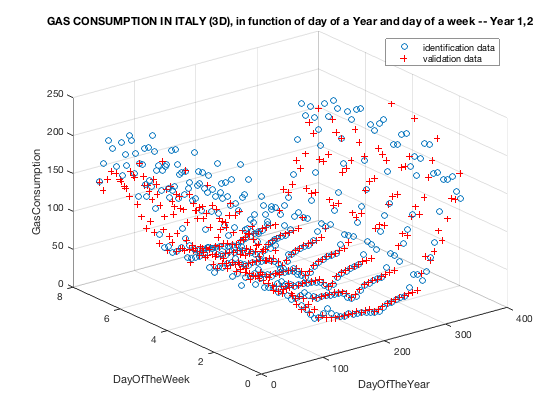

figure
%Plotting identification data
plot3(dsYear1.DayOfTheYear,dsYear1.DayOfTheWeek,dsYear1.GasConsumption,'o');
grid on
title ('GAS CONSUMPTION IN ITALY (3D), in function of day of a Year and day of a week -- Year 1,2');
xlabel('DayOfTheYear');
ylabel('DayOfTheWeek');
zlabel('GasConsumption');
%Plotting validation data
hold on
plot3(dsYear2.DayOfTheYear,dsYear2.DayOfTheWeek,dsYear2.GasConsumption,'r+');
legend('identification data','validation data','Location','Northeast');

Now we estimate the performance of different models, using estimated parameters with new data (validation data).

a. *FIRST DEGREE POLYNOMIAL MODEL*

Phi1Val=[ones(nVal,1), dsYear2.DayOfTheYear, dsYear2.DayOfTheWeek]; 
y_hat1Val=Phi1Val*ThetaLS1;
epsilon1Val=dsYear2.GasConsumption-y_hat1Val;
SSR1Val=epsilon1Val'*epsilon1Val

SSR1Val = 1.0406e+06

%Standard deviation calculation
sd1Val=sqrt(SSR1Val/nVal)

sd1Val = 53.4664

b. *SECOND DEGREE POLYNOMIAL MODEL*

Phi2Val=[ones(nVal,1), dsYear2.DayOfTheYear, dsYear2.DayOfTheWeek ...
    , (dsYear2.DayOfTheYear).^2, (dsYear2.DayOfTheWeek).^2 , (dsYear2.DayOfTheYear).*(dsYear2.DayOfTheWeek)]; 
y_hat2Val=Phi2Val*ThetaLS2;
epsilon2Val=dsYear2.GasConsumption-y_hat2Val;
SSR2Val=epsilon2Val'*epsilon2Val

SSR2Val = 2.1648e+05

%Standard deviation calculation
sd2Val=sqrt(SSR2Val/nVal)

sd2Val = 24.3872

c. *THIRD DEGREE POLYNOMIAL MODEL*

Phi3Val=[ones(nVal,1), dsYear2.DayOfTheYear, dsYear2.DayOfTheWeek ...
    , (dsYear2.DayOfTheYear).^2, (dsYear2.DayOfTheWeek).^2 , (dsYear2.DayOfTheYear).*(dsYear2.DayOfTheWeek) ...
    , (dsYear2.DayOfTheYear).^3, (dsYear2.DayOfTheWeek).^3 ...
    , ((dsYear2.DayOfTheYear).^2).*(dsYear2.DayOfTheWeek), (dsYear2.DayOfTheYear).*((dsYear2.DayOfTheWeek).^2)]; 
y_hat3Val=Phi3Val*ThetaLS3;
epsilon3Val=dsYear2.GasConsumption-y_hat3Val;
SSR3Val=epsilon3Val'*epsilon3Val

SSR3Val = 1.9883e+05

%Standard deviation calculation
sd3Val=sqrt(SSR3Val/nVal)

sd3Val = 23.3718

d.* FOURTH DEGREE POLYNOMIAL MODEL*

Phi4Val=[ones(nVal,1), dsYear2.DayOfTheYear, dsYear2.DayOfTheWeek ...
    , (dsYear2.DayOfTheYear).^2, (dsYear2.DayOfTheWeek).^2 , (dsYear2.DayOfTheYear).*(dsYear2.DayOfTheWeek) ...
    , (dsYear2.DayOfTheYear).^3, (dsYear2.DayOfTheWeek).^3 ...
    , ((dsYear2.DayOfTheYear).^2).*(dsYear2.DayOfTheWeek), (dsYear2.DayOfTheYear).*((dsYear2.DayOfTheWeek).^2) ...
    , (dsYear2.DayOfTheYear).^4, (dsYear2.DayOfTheWeek).^4, ((dsYear2.DayOfTheYear).^3).*(dsYear2.DayOfTheWeek) ...
    , ((dsYear2.DayOfTheYear).^2).*((dsYear2.DayOfTheWeek).^2) ...
    , (dsYear2.DayOfTheYear).*((dsYear2.DayOfTheWeek).^3)];
y_hat4Val=Phi4Val*ThetaLS4;
epsilon4Val=dsYear2.GasConsumption-y_hat4Val;
SSR4Val=epsilon4Val'*epsilon4Val

SSR4Val = 2.2411e+05

%Standard deviation calculation
sd4Val=sqrt(SSR4Val/nVal)

sd4Val = 24.8128

This time, to choose the best model we have to see which is the model that minimizes the SSR (Ssrval) between the data provided by the model and the new data(validation data). In this case, with cross-validation, **the best model is the third degree one.**

Because we'll use in harmonic regression SSRXVal and sdXVal (where x is the degree of the model), we'll save best model figures of merit for polynomial regression in different variables:

SSR3_PR=SSR3+SSR3Val;
sd3_PR=sqrt(SSR3_PR/(n+nVal));

Now we show best model for cross-validation on a 3d graph.

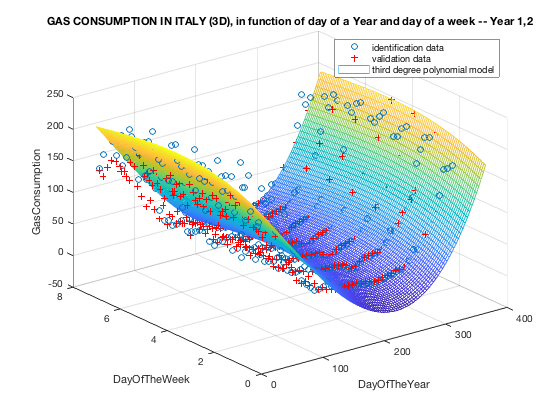

%Plotting identification and validation data on a 3D graph
figure
%Plotting identification data
plot3(dsYear1.DayOfTheYear,dsYear1.DayOfTheWeek,dsYear1.GasConsumption,'o');
grid on
title ('GAS CONSUMPTION IN ITALY (3D), in function of day of a Year and day of a week -- Year 1,2');
xlabel('DayOfTheYear');
ylabel('DayOfTheWeek');
zlabel('GasConsumption');
%Plotting validation data
hold on
plot3(dsYear2.DayOfTheYear,dsYear2.DayOfTheWeek,dsYear2.GasConsumption,'r+');
%Plotting best model for cross-validation (Third degree model)
mesh(Dy,Dw,shape3_matrix);
legend('identification data','validation data', 'third degree polynomial model','Location','Northeast'); 

Some **observations** **on** cross-validation **results**:

- Probably the model identified using matrioska models is not absolutely the best, but it is a model that minimizes the figures of merit of the various criteria (objective and subjective) considered a small group of matrioska models (and therefore is the best model "locally"). The reason why we do not consider all models, as well as for laziness and to avoid that the code gets too heavy, is to avoid that the model goes more and more to sniff out the data noise (their variance from the average value).

- With the cross-validation the best model that results is the third degree, it would have been much better if we had more data related to different years in order to estimate better what really happens.

### 3.2 Neural networks - MLP

For those who are not pretty familiar with neural network "world", you should just know that we are using both abbreviations:

- MLP: Multi-layer Perceptron

- NN: Neural Network

Before analyzing the code you could start with those inks:

- [Perceptron, the base element of a neural network](https://en.wikipedia.org/wiki/Perceptron)

- [What is a MLP-NN? ](https://en.wikipedia.org/wiki/Multilayer_perceptron)

- [Time series forecasting with deep-learning ](https://towardsdatascience.com/time-series-forecasting-with-deep-learning-and-attention-mechanism-2d001fc871fc)

Some useful variables:

% input dataset for the neural network 
% (all the DayOfTheYear-DayOfTheWeek data, both years)
inputDatasetNN = table2array(readtable('../Dataset/gasITAday.xlsx', 'Range', 'A3:B732'));


% output (target) dataset for the neural network
% (all the gas consumption data, both years)
outputDatasetNN = table2array(readtable('../Dataset/gasITAday.xlsx', 'Range', 'C3:C732'));

In fitting problems, you want a neural network to map between a data set of numeric inputs and a set of numeric targets.

Variables used by our NN: 

- x is the input of our neural network architecture

- t is the target  " " " "...

x = inputDatasetNN';
t = outputDatasetNN';

Once selected NN input and output variables, we have to define[ ](https://www.neuraldesigner.com/blog/5_algorithms_to_train_a_neural_network)[the network training algorithm](https://www.neuraldesigner.com/blog/5_algorithms_to_train_a_neural_network)([what does training the NN mean?](https://www.ovh.com/blog/what-does-training-neural-networks-mean/)). 

We've chosen [Bayesian-Regularization backpropagation](https://pubmed.ncbi.nlm.nih.gov/19065804/) algorithm, because it is the more accurate and it will not take us long time to train the net in order to provide good results.

Our figure of merit to minimize is [MSE](https://en.wikipedia.org/wiki/Mean_squared_error). (modify the trainFcn algorithm to see how NN performance changes).

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainbr';  % Bayesian Regularization backpropagation.

Now we can create our network (fitting network, more specifically) **architecture**. 

The architecture of our network is composed by two layer, one hidden layer, and one output layer. We've used 10 neurons in the hidden layer, because in our case this number provides best performance. The [activation function](https://en.wikipedia.org/wiki/Activation_function) in our case is a tanh(z).

% Create a Fitting Network
hiddenLayerSize = 10;
MLPNN_net = fitnet(hiddenLayerSize,trainFcn);

Now we **divide data** in three different groups, one to identify the best model (70% of our data, in our case), one for validation (15%) and one for testing (15%).

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

Once we have done all this stuffs, we are able to **train the NN**.

This script part is the core of the model identification with the neural network, because train a NN model means to find the correct values of **weight **between neurons/perceptrons interconnections ( **train the net means parameterization**/*estimating model parameters*, so consequently overtraining means over-parameterization).

% Train the Network
[MLPNN_net,tr] = train(MLPNN_net,x,t);

Then we can see the output and the **performance of our network**. We also added some criterions used with polynomial regression identification SSR and [standard deviation](https://en.wikipedia.org/wiki/Standard_deviation).

% Test the Network
y = MLPNN_net(x);
e = gsubtract(t,y);
MSE = perform(MLPNN_net,t,y);

SSR_MLP_NN=MSE*length(outputDatasetNN)

SSR_MLP_NN = 2.0470e+05

sdMLP_NN = sqrt(MSE)

sdMLP_NN = 16.7568

Code to see the network architecture and the plot generated by our MLP-NN.

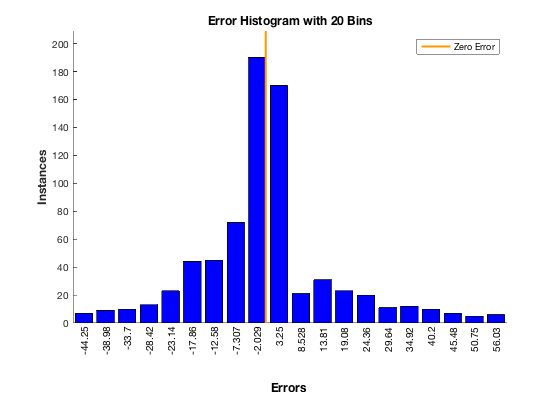

% View the Network
%view(MLPNN_net)

% Plots
% Uncomment these lines to enable various plots.
%figure, plotperform(tr)
%figure, plottrainstate(tr)
ploterrhist(e)

%figure, plotregression(t,y)
%figure, plotfit(MLPNN_net,x,t)

Once all the network "configuration" is complete, we can plot a graph, which shows the difference between real gas consumption and predicted values of gas consumption generated by our MLP-NN.

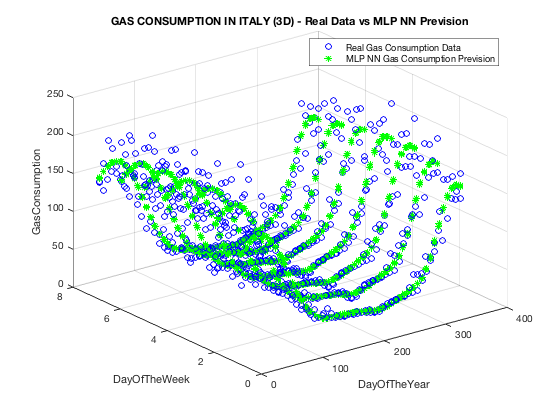

figure
% Real gas consumption data (both two years)
plot3(inputDatasetNN(:,1),inputDatasetNN(:,2), outputDatasetNN, 'bo');
hold on
% MLP NN, gas consumption prevision
plot3(inputDatasetNN(:,1),inputDatasetNN(:,2),  y', 'g*');
grid on
title ('GAS CONSUMPTION IN ITALY (3D) - Real Data vs MLP NN Prevision');
xlabel('DayOfTheYear');
ylabel('DayOfTheWeek');
zlabel('GasConsumption');
legend('Real Gas Consumption Data','MLP NN Gas Consumption Prevision','Location', 'Northeast')

### 3.3 Harmonic regression

[Harmonic regression method theory](http://www.math.yorku.ca/Who/Faculty/Monette/S-news/0510.html).

A further method to identify a model that represents our data can be obtained by using the [Fourier Series theory](https://en.wikipedia.org/wiki/Fourier_series), according to which each signal can be written as a series of sinuses and cosenes. The only parameters to consider and estimate are the coefficients that multiply each sine or cosine term, which is oscillating at a frequency multiple of the fundamental one.

We can note that this identification method follows the same methodology of the polynomial regression, with the difference that we won't use polynomials (whose coefficients have to be estimated), but rather harmonics (so sinuses and cosenes). 

From the observations made in the spectral analysis section we can notice that the two fundamental frequencies of this signal are the annual frequency and the daily one, consequently we will consider cosenes and sinuses oscillating at these fundamental frequencies. What we will have to do is estimate the parameters of these terms and show on a graph the results obtained, based on the latter.

We'll also use cross-validation to understand which is the best model, as we did in the polynomial regression function. The division of the data and the initial observations are the same we discussed previously.

Before analysing the code please read this theoretical reference.

We will not start use costant model but first degree harmonic model. 

#### 3.3.1 Identification

*a. FIRST DEGREE HARMONIC MODEL*

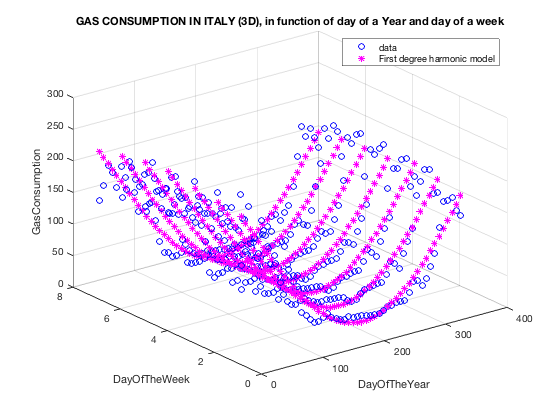

Phi1= [ones(n,1), cos(((pi)/365)*dsYear1.DayOfTheYear), sin(((pi)/365)*dsYear1.DayOfTheYear) ... 
    , cos(((pi)/7)*dsYear1.DayOfTheWeek), sin(((pi)/7)*dsYear1.DayOfTheWeek)]; 
[ThetaLS1, std_thetaLS1] = lscov(Phi1, dsYear1.GasConsumption);

% Variables that will be useful to us regarding the choice of
% best model
q1=length(ThetaLS1); %Number of parameters considered by the model in question
%Estimated yield given our model
y_hat1=Phi1*ThetaLS1;
%Residual calculation
epsilon1=dsYear1.GasConsumption-y_hat1;
%SSR calculation
SSR1=epsilon1'*epsilon1;

figure()
% Plotted on a graph data
plot3(dsYear1.DayOfTheYear,dsYear1.DayOfTheWeek, dsYear1.GasConsumption, 'bo')
hold on
% first degree harmonic function
fun1 = @(a0,a1,b1,c1,d1,x,x2) a0 + a1*cos(x*((pi)/365)) + b1*sin(x*((pi)/365)) + c1*cos(x2*((pi)/7)) + d1*sin(x2*((pi)/7));
% Plotting on graphs identified model
plot3(dsYear1.DayOfTheYear, dsYear1.DayOfTheWeek,fun1(ThetaLS1(1),ThetaLS1(2),ThetaLS1(3),ThetaLS1(4),ThetaLS1(5),dsYear1.DayOfTheYear, dsYear1.DayOfTheWeek), 'm*');
grid on
title ('GAS CONSUMPTION IN ITALY (3D), in function of day of a Year and day of a week');
xlabel('DayOfTheYear');
ylabel('DayOfTheWeek');
zlabel('GasConsumption');
legend( 'data','First degree harmonic model', 'Location', 'Northeast');

*b. SECOND DEGREE HARMONIC MODEL*

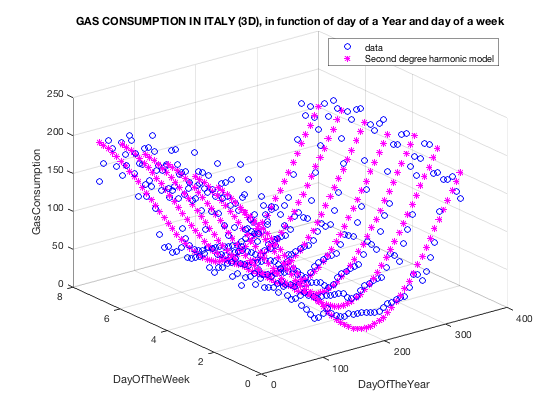

Phi2= [ones(n,1), cos(((pi)/365)*dsYear1.DayOfTheYear), sin(((pi)/365)*dsYear1.DayOfTheYear) ...
    , cos(((pi)/7)*dsYear1.DayOfTheWeek), sin(((pi)/7)*dsYear1.DayOfTheWeek) ...
    , cos(((2*pi)/365)*dsYear1.DayOfTheYear), sin(((2*pi)/365)*dsYear1.DayOfTheYear) ...
    , cos(((2*pi)/7)*dsYear1.DayOfTheWeek), sin(((2*pi)/7)*dsYear1.DayOfTheWeek)]; 
[ThetaLS2, std_thetaLS2] = lscov(Phi2, dsYear1.GasConsumption);

% Variables that will be useful to us regarding the choice of
% best model
q2=length(ThetaLS2); %Number of parameters considered by the model in question
%Estimated yield given our model
y_hat2=Phi2*ThetaLS2;
%Residual calculation
epsilon2=dsYear1.GasConsumption-y_hat2;
%SSR calculation
SSR2=epsilon2'*epsilon2;

figure()
% Plotted on a graph data
plot3(dsYear1.DayOfTheYear,dsYear1.DayOfTheWeek, dsYear1.GasConsumption, 'bo')
hold on
% second degree harmonic function
fun2 = @(a0,a1,b1,c1,d1,a2,b2,c2,d2,x,x2) a0 + a1*cos(x*((pi)/365)) + b1*sin(x*((pi)/365)) + c1*cos(x2*((pi)/7)) + d1*sin(x2*((pi)/7))+ a2*cos(2*x*((pi)/365)) + b2*sin(2*x*((pi)/365)) + c2*cos(2*x2*((pi)/7)) + d2*sin(2*x2*((pi)/7));
% Plotting on graphs identified model
plot3(dsYear1.DayOfTheYear, dsYear1.DayOfTheWeek,fun2(ThetaLS2(1),ThetaLS2(2),ThetaLS2(3),ThetaLS2(4),ThetaLS2(5),ThetaLS2(6),ThetaLS2(7),ThetaLS2(8),ThetaLS2(9),dsYear1.DayOfTheYear, dsYear1.DayOfTheWeek ), 'm*');
grid on
title ('GAS CONSUMPTION IN ITALY (3D), in function of day of a Year and day of a week');
xlabel('DayOfTheYear');
ylabel('DayOfTheWeek');
zlabel('GasConsumption');
legend( 'data','Second degree harmonic model', 'Location', 'Northeast');

*c. THIRD DEGREE HARMONIC MODEL*

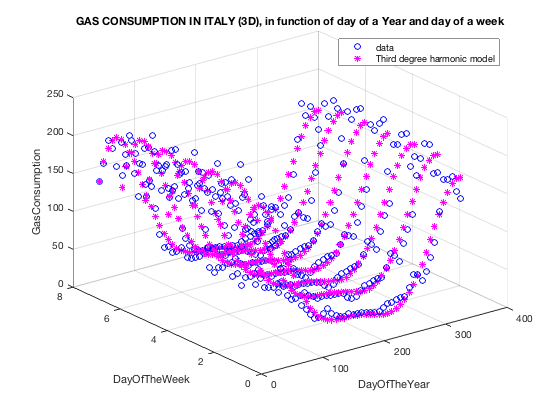

Phi3= [ones(n,1), cos(((pi)/365)*dsYear1.DayOfTheYear), sin(((pi)/365)*dsYear1.DayOfTheYear)...
    , cos(((pi)/7)*dsYear1.DayOfTheWeek), sin(((pi)/7)*dsYear1.DayOfTheWeek) ... 
    , cos(((2*pi)/365)*dsYear1.DayOfTheYear), sin(((2*pi)/365)*dsYear1.DayOfTheYear) ... 
    , cos(((2*pi)/7)*dsYear1.DayOfTheWeek), sin(((2*pi)/7)*dsYear1.DayOfTheWeek) ...
    , cos(((3*pi)/365)*dsYear1.DayOfTheYear), sin(((3*pi)/365)*dsYear1.DayOfTheYear) ...
    , cos(((3*pi)/7)*dsYear1.DayOfTheWeek), sin(((3*pi)/7)*dsYear1.DayOfTheWeek)]; 
[ThetaLS3, std_thetaLS3] = lscov(Phi3, dsYear1.GasConsumption);

% Variables that will be useful to us regarding the choice of
% best model
q3=length(ThetaLS3); %Number of parameters considered by the model in question
%Estimated yield given our model
y_hat3=Phi3*ThetaLS3;
%Residual calculation
epsilon3=dsYear1.GasConsumption-y_hat3;
%SSR calculation
SSR3=epsilon3'*epsilon3;

figure()
% Plotted on a graph data
plot3(dsYear1.DayOfTheYear,dsYear1.DayOfTheWeek, dsYear1.GasConsumption, 'bo')
hold on
% third degree harmonic function
fun3 = @(a0,a1,b1,c1,d1,a2,b2,c2,d2,a3,b3,c3,d3,x,x2) a0 + a1*cos(x*((pi)/365)) + b1*sin(x*((pi)/365)) + c1*cos(x2*((pi)/7)) + d1*sin(x2*((pi)/7)) + a2*cos(2*x*((pi)/365)) + b2*sin(2*x*((pi)/365)) + c2*cos(2*x2*((pi)/7)) + d2*sin(2*x2*((pi)/7)) + a3*cos(3*x*((pi)/365)) + b3*sin(3*x*((pi)/365))+ c3*cos(3*x2*((pi)/7)) + d3*sin(3*x2*((pi)/7));
% Plotting on graphs identified model
plot3(dsYear1.DayOfTheYear, dsYear1.DayOfTheWeek,fun3(ThetaLS3(1),ThetaLS3(2),ThetaLS3(3),ThetaLS3(4),ThetaLS3(5),ThetaLS3(6),ThetaLS3(7),ThetaLS3(8),ThetaLS3(9),ThetaLS3(10),ThetaLS3(11),ThetaLS3(12),ThetaLS3(13),dsYear1.DayOfTheYear, dsYear1.DayOfTheWeek), 'm*');
grid on
title ('GAS CONSUMPTION IN ITALY (3D), in function of day of a Year and day of a week');
xlabel('DayOfTheYear');
ylabel('DayOfTheWeek');
zlabel('GasConsumption');
legend( 'data','Third degree harmonic model', 'Location', 'Northeast');

d. *FOURTH DEGREE HARMONIC MODEL*

Phi4= [ones(n,1), cos(((pi)/365)*dsYear1.DayOfTheYear), sin(((pi)/365)*dsYear1.DayOfTheYear) ...
    , cos(((pi)/7)*dsYear1.DayOfTheWeek), sin(((pi)/7)*dsYear1.DayOfTheWeek) ...
    , cos(((2*pi)/365)*dsYear1.DayOfTheYear), sin(((2*pi)/365)*dsYear1.DayOfTheYear) ... 
    , cos(((2*pi)/7)*dsYear1.DayOfTheWeek), sin(((2*pi)/7)*dsYear1.DayOfTheWeek) ...
    , cos(((3*pi)/365)*dsYear1.DayOfTheYear), sin(((3*pi)/365)*dsYear1.DayOfTheYear) ...
    , cos(((3*pi)/7)*dsYear1.DayOfTheWeek), sin(((3*pi)/7)*dsYear1.DayOfTheWeek) ...
    , cos(((4*pi)/365)*dsYear1.DayOfTheYear), sin(((4*pi)/365)*dsYear1.DayOfTheYear) ...
    , cos(((4*pi)/7)*dsYear1.DayOfTheWeek), sin(((4*pi)/7)*dsYear1.DayOfTheWeek)]; 
[ThetaLS4, std_thetaLS4] = lscov(Phi4, dsYear1.GasConsumption);

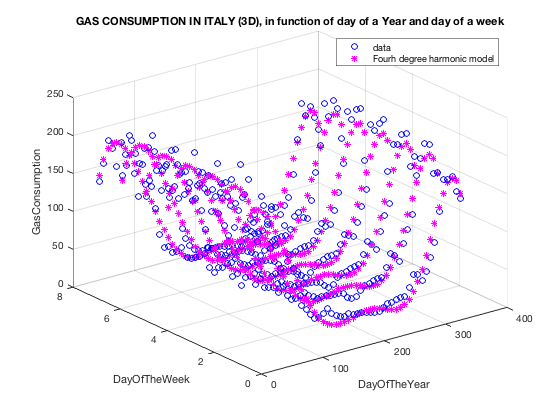


% Variables that will be useful to us regarding the choice of
% best model
q4=length(ThetaLS4); %Number of parameters considered by the model in question
%Estimated yield given our model
y_hat4=Phi4*ThetaLS4;
%Residual calculation
epsilon4=dsYear1.GasConsumption-y_hat4;
%SSR calculation
SSR4=epsilon4'*epsilon4;

figure()
% Plotted on a graph data
plot3(dsYear1.DayOfTheYear,dsYear1.DayOfTheWeek, dsYear1.GasConsumption, 'bo')
hold on
% fourth degree harmonic function
fun4 = @(a0,a1,b1,c1,d1,a2,b2,c2,d2,a3,b3,c3,d3,a4,b4,c4,d4,x,x2) a0 + a1*cos(x*((pi)/365)) + b1*sin(x*((pi)/365)) + c1*cos(x2*((pi)/7)) + d1*sin(x2*((pi)/7)) + a2*cos(2*x*((pi)/365)) + b2*sin(2*x*((pi)/365)) + c2*cos(2*x2*((pi)/7)) + d2*sin(2*x2*((pi)/7)) + a3*cos(3*x*((pi)/365)) + b3*sin(3*x*((pi)/365))+ c3*cos(3*x2*((pi)/7)) + d3*sin(3*x2*((pi)/7)) + a4*cos(4*x*((pi)/365)) + b4*sin(4*x*((pi)/365)) + c4*cos(4*x2*((pi)/7)) + d4*sin(4*x2*((pi)/7));
% Plotting on graphs identified model
plot3(dsYear1.DayOfTheYear, dsYear1.DayOfTheWeek,fun4(ThetaLS4(1),ThetaLS4(2),ThetaLS4(3),ThetaLS4(4),ThetaLS4(5),ThetaLS4(6),ThetaLS4(7),ThetaLS4(8),ThetaLS4(9),ThetaLS4(10),ThetaLS4(11),ThetaLS4(12),ThetaLS4(13),ThetaLS4(14),ThetaLS4(15),ThetaLS4(16),ThetaLS4(17),dsYear1.DayOfTheYear,dsYear1.DayOfTheWeek), 'm*');
grid on
title ('GAS CONSUMPTION IN ITALY (3D), in function of day of a Year and day of a week');
xlabel('DayOfTheYear');
ylabel('DayOfTheWeek');
zlabel('GasConsumption');
legend( 'data','Fourh degree harmonic model', 'Location', 'Northeast');

*COMPARISON BETWEEN THE DIFFERENT MODELS IDENTIFIED*

As we did with polynomial regression, we will use some criterions to compare different harmonic models identified before. 

- SSR 

SSR1

SSR1 = 2.2866e+05

SSR2

SSR2 = 1.9734e+05

SSR3

SSR3 = 1.0366e+05

SSR4

SSR4 = 8.8537e+04

- Test F

%Compare: FIRST DEGREE ARMONIC vs SECOND DEGREE ARMONIC 
falpha2=finv(1-alpha, 1, n-q2)

falpha2 = 3.8678

f2= (n-q2)*((SSR1-SSR2)/SSR2)

f2 = 56.3509

%Compare: SECOND DEGREE ARMONIC vs THIRD DEGREE ARMONIC
falpha3=finv(1-alpha, 1, n-q3)

falpha3 = 3.8681

f3= (n-q3)*((SSR2-SSR3)/SSR3)

f3 = 317.1872

%Compare: THIRD DEGREE ARMONIC vs FOURTH DEGREE ARMONIC
falpha4=finv(1-alpha, 1, n-q4)

falpha4 = 3.8684

f4= (n-q4)*((SSR3-SSR4)/SSR4)

f4 = 59.2795

**Fisher's Test says the better model is the 4th degree harmonic.**

- FPE, MDL, AIC

%Objective criteria for the first degree model:
FPE1= ((n+q1)/(n-q1))*SSR1

FPE1 = 2.3503e+05

MDL1= ((log(n)*q1)/n)+log(SSR1)

MDL1 = 12.4210

AIC1= ((2*q1)/n) + log(SSR1)

AIC1 = 12.3675

%Objective criteria for the second degree model:
FPE2= ((n+q2)/(n-q2))*SSR2

FPE2 = 2.0734e+05

MDL2= ((log(n)*q2)/n)+log(SSR2)

MDL2 = 12.3385

AIC2= ((2*q2)/n) + log(SSR2)

AIC2 = 12.2421

%Objective criteria for the third degree model:
FPE3= ((n+q3)/(n-q3))*SSR3

FPE3 = 1.1134e+05

MDL3= ((log(n)*q3)/n)+log(SSR3)

MDL3 = 11.7595

AIC3= ((2*q3)/n) + log(SSR3)

AIC3 = 11.6203

%Objective criteria for the fourth degree model:
FPE4= ((n+q4)/(n-q4))*SSR4

FPE4 = 9.7212e+04

MDL4= ((log(n)*q4)/n)+log(SSR4)

MDL4 = 11.6666

AIC4= ((2*q4)/n) + log(SSR4)

AIC4 = 11.4846

Now we choose as the optimal model (of the single objective test), the one that minimizes the amount of merit between the different models considered.

**We note that for AIC, MDL & FPE, the better model is the fourth degree harmonic model.**

- Another criterion ("*dogma*")

#### 3.3.2 Cross-validation

Cross-validation theory and initial observations (the same as polynomial regression).

Let's plot both identification and validation data.

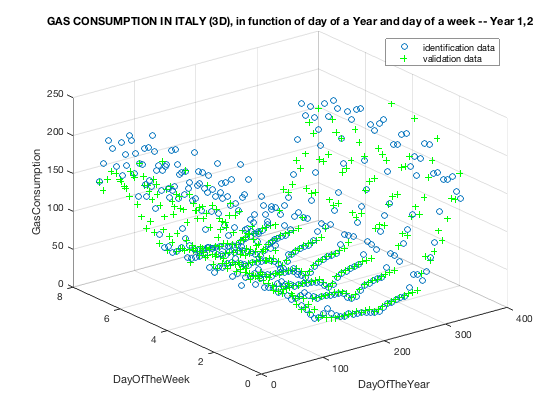

figure
%Plotting identification data
plot3(dsYear1.DayOfTheYear,dsYear1.DayOfTheWeek,dsYear1.GasConsumption,'o');
grid on
title ('GAS CONSUMPTION IN ITALY (3D), in function of day of a Year and day of a week -- Year 1,2');
xlabel('DayOfTheYear');
ylabel('DayOfTheWeek');
zlabel('GasConsumption');
%Plotting validation data
hold on
plot3(dsYear2.DayOfTheYear,dsYear2.DayOfTheWeek,dsYear2.GasConsumption,'g+');
legend('identification data','validation data','Location','Northeast');

Now we estimate the performance of different harmonic models, using estimated parameters with new data (validation data).

a. *FIRST DEGREE HARMONIC MODEL*

Phi1Val=[ones(nVal,1), cos(((pi)/365)*dsYear2.DayOfTheYear), sin(((pi)/365)*dsYear2.DayOfTheYear) ... 
    , cos(((pi)/7)*dsYear2.DayOfTheWeek), sin(((pi)/7)*dsYear2.DayOfTheWeek)]; 
y_hat1Val=Phi1Val*ThetaLS1;
epsilon1Val=dsYear2.GasConsumption-y_hat1Val;
SSR1Val=epsilon1Val'*epsilon1Val

SSR1Val = 2.1602e+05

%Standard deviation calculation
sd1Val=sqrt(SSR1Val/nVal)

sd1Val = 24.3613

b. *SECOND DEGREE HARMONIC MODEL*

Phi2Val= [ones(nVal,1), cos(((pi)/365)*dsYear2.DayOfTheYear), sin(((pi)/365)*dsYear2.DayOfTheYear) ...
    , cos(((pi)/7)*dsYear2.DayOfTheWeek), sin(((pi)/7)*dsYear2.DayOfTheWeek) ...
    , cos(((2*pi)/365)*dsYear2.DayOfTheYear), sin(((2*pi)/365)*dsYear2.DayOfTheYear) ...
    , cos(((2*pi)/7)*dsYear2.DayOfTheWeek), sin(((2*pi)/7)*dsYear2.DayOfTheWeek)];
y_hat2Val=Phi2Val*ThetaLS2;
epsilon2Val=dsYear2.GasConsumption-y_hat2Val;
SSR2Val=epsilon2Val'*epsilon2Val

SSR2Val = 2.2555e+05

%Standard deviation calculation
sd2Val=sqrt(SSR2Val/nVal)

sd2Val = 24.8925

c. *THIRD DEGREE HARMONIC MODEL*

Phi3Val= [ones(nVal,1), cos(((pi)/365)*dsYear2.DayOfTheYear), sin(((pi)/365)*dsYear2.DayOfTheYear)...
    , cos(((pi)/7)*dsYear2.DayOfTheWeek), sin(((pi)/7)*dsYear2.DayOfTheWeek) ... 
    , cos(((2*pi)/365)*dsYear2.DayOfTheYear), sin(((2*pi)/365)*dsYear2.DayOfTheYear) ... 
    , cos(((2*pi)/7)*dsYear2.DayOfTheWeek), sin(((2*pi)/7)*dsYear2.DayOfTheWeek) ...
    , cos(((3*pi)/365)*dsYear2.DayOfTheYear), sin(((3*pi)/365)*dsYear2.DayOfTheYear) ...
    , cos(((3*pi)/7)*dsYear2.DayOfTheWeek), sin(((3*pi)/7)*dsYear2.DayOfTheWeek)]; 
y_hat3Val=Phi3Val*ThetaLS3;
epsilon3Val=dsYear2.GasConsumption-y_hat3Val;
SSR3Val=epsilon3Val'*epsilon3Val

SSR3Val = 2.0815e+05

%Standard deviation calculation
sd3Val=sqrt(SSR3Val/nVal)

sd3Val = 23.9129

d. *FOURTH DEGREE HARMONIC MODEL*

Phi4Val= [ones(nVal,1), cos(((pi)/365)*dsYear2.DayOfTheYear), sin(((pi)/365)*dsYear2.DayOfTheYear) ...
    , cos(((pi)/7)*dsYear2.DayOfTheWeek), sin(((pi)/7)*dsYear2.DayOfTheWeek) ...
    , cos(((2*pi)/365)*dsYear2.DayOfTheYear), sin(((2*pi)/365)*dsYear2.DayOfTheYear) ... 
    , cos(((2*pi)/7)*dsYear2.DayOfTheWeek), sin(((2*pi)/7)*dsYear2.DayOfTheWeek) ...
    , cos(((3*pi)/365)*dsYear2.DayOfTheYear), sin(((3*pi)/365)*dsYear2.DayOfTheYear) ...
    , cos(((3*pi)/7)*dsYear2.DayOfTheWeek), sin(((3*pi)/7)*dsYear2.DayOfTheWeek) ...
    , cos(((4*pi)/365)*dsYear2.DayOfTheYear), sin(((4*pi)/365)*dsYear2.DayOfTheYear) ...
    , cos(((4*pi)/7)*dsYear2.DayOfTheWeek), sin(((4*pi)/7)*dsYear2.DayOfTheWeek)]; 
y_hat4Val=Phi4Val*ThetaLS4;
epsilon4Val=dsYear2.GasConsumption-y_hat4Val;
SSR4Val=epsilon4Val'*epsilon4Val

SSR4Val = 2.2949e+05

%Standard deviation calculation
sd4Val=sqrt(SSR4Val/nVal)

sd4Val = 25.1089

This time, we choose the best model checking which is the ones that minimizes the SSR (Ssrval) between the data provided by the model and the new data, that is those of validation. **In this case, with cross-validation, the best model is the third degree one.**

Because we already used in polynomial regression SSRXVal and sdXVal (where x is the degree of the model), we will save best model figures of merit for harmonic regression in different variables:

SSR3_HR=SSR3+SSR3Val;
sd3_HR=sqrt(SSR3_HR/(n+nVal));

Now we show best model for cross-validation on a 3d graph.

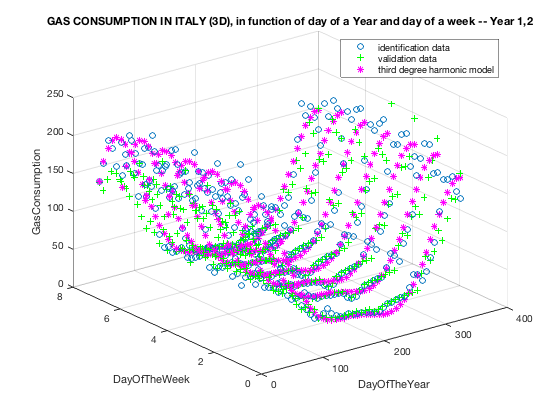

figure
%Plotting identification data
plot3(dsYear1.DayOfTheYear,dsYear1.DayOfTheWeek,dsYear1.GasConsumption,'o');
grid on
title ('GAS CONSUMPTION IN ITALY (3D), in function of day of a Year and day of a week -- Year 1,2');
xlabel('DayOfTheYear');
ylabel('DayOfTheWeek');
zlabel('GasConsumption');
%Plotting validation data
hold on
plot3(dsYear2.DayOfTheYear,dsYear2.DayOfTheWeek,dsYear2.GasConsumption,'g+');
%Plotting best model for cross-validation (Third degree model)
plot3(dsYear1.DayOfTheYear, dsYear1.DayOfTheWeek,fun3(ThetaLS3(1),ThetaLS3(2),ThetaLS3(3),ThetaLS3(4),ThetaLS3(5),ThetaLS3(6),ThetaLS3(7),ThetaLS3(8),ThetaLS3(9),ThetaLS3(10),ThetaLS3(11),ThetaLS3(12),ThetaLS3(13),dsYear1.DayOfTheYear, dsYear1.DayOfTheWeek), 'm*');
legend('identification data','validation data', 'third degree harmonic model','Location','Northeast'); 

The same conclusions of the cross-validation section, in the polynomial regression, are still valid in this regression method.

### 3.4 Comparison between models

In order to decide which model is better, we will compare them using basically two figures of merit: SSR and standard deviation.

In this code we replicate some script lines wrote before, to show the results performed by different identification model methods

% Polinomial regression (3rd degree polynomial model)
SSR3_PR

SSR3_PR = 4.1300e+05

sd3_PR

sd3_PR = 23.8182

% Neural network-MLP
SSR_MLP_NN

SSR_MLP_NN = 2.0470e+05

sdMLP_NN

sdMLP_NN = 16.7568

% Harmonic regression (3rd degree harmonic model) 
SSR3_HR

SSR3_HR = 3.1181e+05

sd3_HR

sd3_HR = 20.6956

Note that all three models identified are producing **results**, in terms of merit figures, **very close** to each other. In conclusion, the choice of one model instead of another one do not cause significant changes.

Another important point is that in the **MLP** model provides a **different result** **every** **"running section" time**, this is caused by the fact that when we identify the best model we are training our net again and again, and this will generate different results due to different initial conditions and sampling.

In conclusion, most of the times, the MLP NN is the model that supplies better results (even if there is not  a great difference considering the model obtained with polynomial regression).

## ***4. Prediction function***

Once identified the best model, another aim is to write a script/function which predicts the gas consumption in function of a day of the year and a day of the week (as parameters). 

The best model, in terms of SSR and standard deviation, is the MLP-NN and we will use it to perform this task.

#### 4.1 Insert parameters and call function

Here's the script to call the *prediz(dy, dw) *function, you should insert the day of the week (dw) and the day of the year (dy).

You can also change manually the variables of the day of the week and the day of the year in order to see how the gas consumption prediction changes.

% Insert parameters value
% Remember that in DayOfTheWeek notation 1 is Sunday, 7 
% is Saturday
DayOfTheWeek=3

DayOfTheWeek = 3

DayOfTheYear=355

DayOfTheYear = 355


% Call the prediction function, and passing the parameters useful
% to perform prediction
s_hat = prediz([DayOfTheYear DayOfTheWeek])

s_hat = 175.9877

#### 4.2 Implemented function 

This function predicts the gas consumption, once you passed two parameter (Day of the year and day of the week). Note that it is based on the same characteristics of the neural network that we used in the model identification section (link).  

function Y = prediz(X)
%MYNEURALNETWORKFUNCTION neural network simulation function.
%
% [Y] = myNeuralNetworkFunction(X,~,~) takes these arguments:
%
%   X = 1xTS cell, 1 inputs over TS timesteps
%   Each X{1,ts} = Qx2 matrix, input #1 at timestep ts.
%
% and returns:
%   Y = 1xTS cell of 1 outputs over TS timesteps.
%   Each Y{1,ts} = Qx1 matrix, output #1 at timestep ts.
%
% where Q is number of samples (or series) and TS is the number of timesteps.

%#ok<*RPMT0>

% ===== NEURAL NETWORK CONSTANTS =====

% Input 1
x1_step1.xoffset = [1;1];
x1_step1.gain = [0.00549450549450549;0.333333333333333];
x1_step1.ymin = -1;

% Layer 1
b1 = [1.6525686164181392357;4.37878166127478341;0.39385287561035992043;1.5763426505213087303;1.9773116487138624464;0.82009873529226762212;-0.9453845144276359358;-1.4146111982504598892;0.45703922143447001103;0.92099719305288563209];
IW1_1 = [-3.8458266490110877278 -0.06770365427983426887;-5.6397477541688099123 -0.087245651823287515003;-0.20240367283691632072 0.1050131850081507251;-1.9596780833887161855 -0.078769527515405904361;3.4025126475728044717 0.042065989222683349003;-1.7374750719987037684 -0.037810168768017807239;-1.4157915629468367236 -0.098047019484656341981;0.061960942478370500952 -0.88126320374738487118;-0.19214827290861669074 0.097089931639632587324;1.314446980456108971 0.92541312964731181623];

% Layer 2
b2 = -1.3877428517168444166;
LW2_1 = [-1.2432151693218183031 -1.8267177422800271458 -0.82147402787392420631 2.5112280322332449778 -2.1013197250860069509 1.536102316808938717 -2.9367855770632318446 -1.1819748847612310261 -0.8636085777285191778 -0.43775230572996903788];

% Output 1
y1_step1.ymin = -1;
y1_step1.gain = 0.00902961850313305;
y1_step1.xoffset = 17.0764;

% ===== SIMULATION ========

% Format Input Arguments
isCellX = iscell(X);
if ~isCellX
    X = {X};
end

% Dimensions
TS = size(X,2); % timesteps
if ~isempty(X)
    Q = size(X{1},1); % samples/series
else
    Q = 0;
end

% Allocate Outputs
Y = cell(1,TS);

% Time loop
for ts=1:TS
    
    % Input 1
    X{1,ts} = X{1,ts}';
    Xp1 = mapminmax_apply(X{1,ts},x1_step1);
    
    % Layer 1
    a1 = tansig_apply(repmat(b1,1,Q) + IW1_1*Xp1);
    
    % Layer 2
    a2 = repmat(b2,1,Q) + LW2_1*a1;
    
    % Output 1
    Y{1,ts} = mapminmax_reverse(a2,y1_step1);
    Y{1,ts} = Y{1,ts}';
end

% Final Delay States
Xf = cell(1,0);
Af = cell(2,0);

% Format Output Arguments
if ~isCellX
    Y = cell2mat(Y);
end
end

% ===== MODULE FUNCTIONS ========

%Map Minimum and Maximum Input Processing Function
function y = mapminmax_apply(x,settings)
y = bsxfun(@minus,x,settings.xoffset);
y = bsxfun(@times,y,settings.gain);
y = bsxfun(@plus,y,settings.ymin);
end

% Sigmoid Symmetric Transfer Function
function a = tansig_apply(n,~)
a = 2 ./ (1 + exp(-2*n)) - 1;
end

% Map Minimum and Maximum Output Reverse-Processing Function
function x = mapminmax_reverse(y,settings)
x = bsxfun(@minus,y,settings.ymin);
x = bsxfun(@rdivide,x,settings.gain);
x = bsxfun(@plus,x,settings.xoffset);
end

## ***5. Conclusion***

#### 5.1 The usefulness of identifying models and data analysis

The identification of models is a really useful tool, which allows you to make predictions built on data in possession of any process that we are considering.

Considering forecasts only to the case of gas consumption is restrictive, you can think of a **myriad of other applications** of this theory. For example seeing if it is convenient to invest in a share on the stock exchange (based on its trend and the forecasts we are making), or maybe viewing the trend of the covid infection to decide which restrictive measures to apply, and so on. 

The identification of the models and therefore the analysis of the data is an important component, among other things, in the **"decision making"** process.

#### ***5.2 Observation on our model and its forecast***

Note that the best model was built on the basis of the data in our possession. If you want to predict the gas consumption in an abnormal situation (Covid 19), you have to accept that the forecast might be very different from what actually happens. 

This is because the Covid-19 has led to the temporary closure of many factories, with a consequence on the trend of gas consumption (it has clearly decreased). Clearly you have to keep a lot of "variables" in mind, to predict those kind of trend.